# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 1

T = 1

macroItrMax = 100; % Max no. of permissible iterations for optimizing an area
noBatteries = true;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;

DER_percent = 100;
Batt_percent = DER_percent;
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = false;


% delta_t = 0.25; % 15 minutes = 0.25 hours
delta_t = 1.00;
% globalPVCoeff = 2.3;
globalPVCoeff = 1.0;
% lambdaVals = generateLoadProfile(T, 1.0, 1.1, 'upwards')
% lambdaVals = generateLoadProfile(T, 1.0, 1.4, 'upwards')
lambdaVals = generateLoadProfile(T, 1.0, 1.0, 'upwards')

lambdaVals = 1

loadVals = lambdaVals*3

loadVals = 3

% pvCoeffVals = globalPVCoeff*generatePVProfile(T, 0.8, 1.2, 0.9)
% % pvCoeffVals = globalPVCoeff*generatePVProfile(T, 1.0, 1.0, 1.0)

% costArray0 = [-1.0, 0.0, 0.7, 1.2, 1.5, 1.7, 6.4, 5.4, 2.5, 2.5, 3.2, 3.6, 2.2, 1.9, 1.8, 1.9, 2.9, 5.0, 4.6, 4.5, 4.4, 4.0, 2.8, 4.9]';
costArray0 = [1.6, 3.8, 1.7, 1.8, 2.1, 2.2, 2.4, 2.9, 4.4, 5.1, 4.3, 3.5, 2.8, 2.8, 2.3, 2.0, 2.3, 4.1, 3.4, 6.6, 4.7, 4.7, 5.0, 2.6]';
costArray = choose_middle_T_points(costArray0, T);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

% actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;
PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);

sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;

simInfo = struct();
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);
% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);
S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T)
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T)

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        
        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T)
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};
        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
    
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij)'; %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij)'; %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj)'; %N_Areax1
        
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        PSubs_allT_vs_macroItr(macroItr+1) = PSubs_allT_vs_macroItr(macroItr+1) + areaInfo.PSubs_allT;
        PSubs_1toT_vs_macroItr(1:T, macroItr+1) = PSubs_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubs_1toT;
        PSubsCost_allT_vs_macroItr(macroItr+1) = PSubsCost_allT_vs_macroItr(macroItr+1) + areaInfo.PSubsCost_allT;
        PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PSubsCost_1toT;

        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.Ploss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        % keyboard
    end
    
    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    % first let's quickly compute system losses for the macroItr first and
    % store them
    
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T)
            S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T)
    
            delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;

            delta_v_1toT = v_parentSide_1toT - v_childSide_1toT
    
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
    
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr+1, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T)
                    disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr+1, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T)
                    disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T)
                    disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
    
            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =      0
     0


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.401e-02  
    1         370    1.010614e-10     3.055e-02     1.000e+00     5.083e-01     1.735e-01  
    2         555    3.578002e-04     1.315e-06     1.000e+00     4.980e-02     2.887e-02  
    3         740    3.576192e-04     3.235e-08     1.000e+00     4.319e-04     1.769e-04  
    4         925    3.567062e-04     7.905e-07     1.000e+00     2.138e-03     1.669e-04  
    5        1110    3.526080e-04     1.778e-05     1.000e+00     1.015e-02     1.266e-04  
    6        1295    3.470185e-04     7.027e-05     1.000e+00     2.009e-02     7.996e-05  
    7        1480    3.473715e-04     4.352e-05     1.000e+00     1.596e-02     1.866e-04  
    8        1665    3.483164e-04     4.928e-06     1.000e+00     5.315e-03     5.

xVals_Area_1toT =     0.1738
    0.1738
    0.0046
    0.0228
    0.0091
    0.0137
    0.0091
    0.1372
    0.1326
    0.0228


Macro-iteration 1: Running OPF for Area 2.


v_parAr_1toT = 1.0609

S_chArs_1toT = 0

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     1.415e-02  
    1         172    7.866082e-11     1.587e-02     1.000e+00     3.962e-01     1.256e-01  
    2         258    3.654481e-04     2.010e-07     1.000e+00     3.136e-02     1.504e-02  
    3         344    3.653660e-04     1.577e-08     1.000e+00     2.896e-04     1.221e-04  
    4         430    3.649592e-04     3.811e-07     1.000e+00     1.427e-03     1.108e-04  
    5         516    3.632156e-04     8.183e-06     1.000e+00     6.632e-03     7.407e-05  
    6         602    3.614595e-04     2.688e-05     1.000e+00     1.207e-02     4.082e-05  
    7         688    3.624779e-04     2.339e-09     1.000e+00     1.410e-04     4.049e-05  
    8         774    3.624489e-04     1.458e-08     1.000e+00     3.411e-04     4.

xVals_Area_1toT =     0.1259
    0.1259
    0.1167
    0.1076
    0.0091
    0.0046
    0.0984
    0.0091
    0.0046
    0.0893


Macro-iteration 1: Running OPF for Area 3.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     6.090e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.672909e-11     2.984e-02     1.000e+00     4.543e-01     1.724e-01  
    2         276    2.841312e-04     3.528e-07     1.000e+00     5.254e-02     2.821e-02  
    3         368    2.841116e-04     3.460e-09     1.000e+00     1.439e-04     5.851e-05  
    4         460    2.840097e-04     8.561e-08     1.000e+00     7.144e-04     5.704e-05  
    5         552    2.835357e-04     2.004e-06     1.000e+00     3.449e-03     4.988e-05  
    6         645    2.826443e-04     2.951e-08     1.000e+00     1.430e-02     3.780e-05  
    7         738    2.826161e-04     3.447e-10     1.000e+00     2.422e-03     3.480e-05  
    8         830    2.826042e-04     7.278e-08     1.000e+00     6.172e-04     3.

xVals_Area_1toT =     0.1727
    0.1727
    0.0183
    0.0091
    0.0091
    0.0046
    0.1452
    0.0046
    0.1405
    0.0091


Macro-iteration 1: Running OPF for Area 4.


v_parAr_1toT = 1.0609


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.705183e-10     1.061e-01     1.000e+00     8.590e-01     3.253e-01  
    2         750    1.082272e-03     7.579e-06     1.000e+00     1.882e-01     1.006e-01  
    3        1000    1.082123e-03     1.991e-08     1.000e+00     4.497e-04     1.446e-04  
    4        1250    1.081741e-03     9.475e-08     1.000e+00     9.910e-04     1.446e-04  
    5        1500    1.079985e-03     2.187e-06     1.000e+00     4.755e-03     1.446e-04  
    6        1751    1.077388e-03     1.722e-08     1.000e+00     1.762e-02     1.446e-04  
    7        2002    1.077347e-03     1.246e-11     1.000e+00     1.326e-03     5.108e-05  
    8        2253    1.077278e-03     4.264e-12     1.000e+00     1.647e-03     5.

xVals_Area_1toT =     0.3264
    0.3264
    0.3264
    0.0274
    0.0228
    0.0137
    0.0091
    0.1981
    0.0274
    0.0183


Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 3.6465e-21 + 2.1910e-21i

S12_intoChild_1toT = 0.1259 - 0.0005i

delta_S12_1toT = -0.1259 + 0.0005i

delta_v_1toT = -0.0036

Macro-iteration 1: Current Biggest Residual is 1.259405e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = -1.5036e-22 + 5.5863e-21i

S12_intoChild_1toT = 0.1727 - 0.0005i

delta_S12_1toT = -0.1727 + 0.0005i

delta_v_1toT = -0.0050

Macro-iteration 1: Current Biggest Residual is 1.726690e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = -6.8856e-21 + 7.3046e-21i

S12_intoChild_1toT = 0.3264 - 0.0011i

delta_S12_1toT = -0.3264 + 0.0011i

delta_v_1toT = -0.0037

Macro-iteration 1: Current Biggest Residual is 3.264021e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0573
    1.0609
    1.0609


    1.0573



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1259 - 0.0005i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


   0.1259 - 0.0005i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0573
    1.0559
    1.0609


    1.0559



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1259 - 0.0005i
   0.1727 - 0.0005i
   0.0000 + 0.0000i


   0.1727 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


v1_1toT =     1.0609
    1.0573
    1.0559
    1.0572


    1.0572



***Macro-iteration 1 Communication Power:****


S12_allRelationships_1toT =    0.1259 - 0.0005i
   0.1727 - 0.0005i
   0.3264 - 0.0011i


   0.3264 - 0.0011i



Macro-iteration 2: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.1259 - 0.0005i
   0.1727 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     1.727e-01     1.000e+00     0.000e+00     2.401e-02  
    1         372    8.531498e-11     8.806e-02     4.900e-01     5.389e-01     2.313e-01  
    2         557    2.129846e-03     5.404e-02     1.000e+00     6.512e-01     1.662e-01  
    3         742    2.811497e-03     1.678e-06     1.000e+00     1.040e-01     1.927e-02  
    4         927    2.811368e-03     1.928e-08     1.000e+00     3.691e-04     1.380e-04  
    5        1112    2.810701e-03     4.728e-07     1.000e+00     1.826e-03     1.316e-04  
    6        1297    2.807718e-03     1.066e-05     1.000e+00     8.662e-03     1.007e-04  
    7        1482    2.804148e-03     3.395e-05     1.000e+00     1.537e-02     7.592e-05  
    8        1667    2.803815e-03     3.335e-05     1.000e+00     1.524e-02     2.

xVals_Area_1toT =     0.4749
    0.4749
    0.0046
    0.0228
    0.0091
    0.0137
    0.0091
    0.4375
    0.4324
    0.0228


Macro-iteration 2: Running OPF for Area 2.


v_parAr_1toT = 1.0573

S_chArs_1toT = 0.3264 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.264e-01     1.000e+00     0.000e+00     1.415e-02  
    1         175    5.726630e-11     2.144e-01     3.430e-01     3.931e-01     1.550e-01  
    2         261    2.003170e-03     8.509e-02     1.000e+00     8.030e-01     1.188e-01  
    3         347    3.434036e-03     2.704e-06     1.000e+00     1.924e-01     4.982e-02  
    4         433    3.433984e-03     1.289e-08     1.000e+00     2.525e-04     1.103e-04  
    5         519    3.433675e-03     3.110e-07     1.000e+00     1.243e-03     1.011e-04  
    6         605    3.432347e-03     6.692e-06     1.000e+00     5.785e-03     7.132e-05  
    7         692    3.431761e-03     3.472e-08     1.000e+00     1.080e-02     5.243e-05  
    8         778    3.431750e-03     3.085e-09     1.000e+00     1.582e-04     4.

xVals_Area_1toT =     0.4554
    0.4554
    0.4455
    0.4360
    0.0091
    0.0046
    0.4266
    0.0091
    0.0046
    0.4169


Macro-iteration 2: Running OPF for Area 3.


v_parAr_1toT = 1.0559


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.591e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.640897e-11     2.983e-02     1.000e+00     4.419e-01     1.724e-01  
    2         276    2.853367e-04     3.182e-07     1.000e+00     5.276e-02     2.833e-02  
    3         368    2.853183e-04     3.448e-09     1.000e+00     1.392e-04     5.841e-05  
    4         460    2.852228e-04     8.529e-08     1.000e+00     6.913e-04     5.689e-05  
    5         552    2.847789e-04     1.995e-06     1.000e+00     3.338e-03     4.949e-05  
    6         645    2.839436e-04     2.987e-08     1.000e+00     1.384e-02     3.903e-05  
    7         738    2.839171e-04     3.518e-10     1.000e+00     2.351e-03     3.383e-05  
    8         830    2.839061e-04     7.001e-08     1.000e+00     5.915e-04     3.

xVals_Area_1toT =     0.1727
    0.1727
    0.0183
    0.0091
    0.0091
    0.0046
    0.1452
    0.0046
    0.1405
    0.0091


Macro-iteration 2: Running OPF for Area 4.


v_parAr_1toT = 1.0572


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.697139e-10     1.061e-01     1.000e+00     8.459e-01     3.253e-01  
    2         750    1.085503e-03     6.762e-06     1.000e+00     1.888e-01     1.009e-01  
    3        1000    1.085368e-03     1.894e-08     1.000e+00     4.263e-04     1.344e-04  
    4        1250    1.085010e-03     9.668e-08     1.000e+00     9.726e-04     1.334e-04  
    5        1500    1.083366e-03     2.227e-06     1.000e+00     4.662e-03     1.334e-04  
    6        1751    1.081032e-03     1.370e-08     1.000e+00     1.667e-02     1.355e-04  
    7        2002    1.080993e-03     1.356e-11     1.000e+00     1.354e-03     4.815e-05  
    8        2253    1.080934e-03     2.757e-12     1.000e+00     1.478e-03     4.

xVals_Area_1toT =     0.3264
    0.3264
    0.3264
    0.0274
    0.0228
    0.0137
    0.0091
    0.1981
    0.0274
    0.0183


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.1259 - 0.0005i

S12_intoChild_1toT = 0.4554 - 0.0055i

delta_S12_1toT = -0.3295 + 0.0050i

delta_v_1toT = -0.0071

Macro-iteration 2: Current Biggest Residual is 3.295068e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1727 - 0.0005i

S12_intoChild_1toT = 0.1727 - 0.0005i

delta_S12_1toT = -8.4277e-07 + 4.8452e-06i

delta_v_1toT = -0.0099

Macro-iteration 2: Current Biggest Residual is 9.945041e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3264 - 0.0011i

S12_intoChild_1toT = 0.3264 - 0.0011i

delta_S12_1toT = -2.0536e-06 + 3.5176e-06i

delta_v_1toT = -0.0154

Macro-iteration 2: Current Biggest Residual is 1.543859e-02 at index 2.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0502
    1.0559
    1.0572


    1.0502



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4554 - 0.0055i
   0.1727 - 0.0005i
   0.3264 - 0.0011i


   0.4554 - 0.0055i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0502
    1.0460
    1.0572


    1.0460



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4554 - 0.0055i
   0.1727 - 0.0005i
   0.3264 - 0.0011i


   0.1727 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


v1_1toT =     1.0609
    1.0502
    1.0460
    1.0417


    1.0417



***Macro-iteration 2 Communication Power:****


S12_allRelationships_1toT =    0.4554 - 0.0055i
   0.1727 - 0.0005i
   0.3264 - 0.0011i


   0.3264 - 0.0011i



Macro-iteration 3: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4554 - 0.0055i
   0.1727 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.554e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.581790e-11     3.461e-01     2.401e-01     4.414e-01     1.925e-01  
    2         561    1.588497e-03     1.765e-01     4.900e-01     7.411e-01     1.347e-01  
    3         746    6.397505e-03     9.010e-02     1.000e+00     1.108e+00     1.378e-01  
    4         931    7.441495e-03     2.525e-06     1.000e+00     1.828e-01     2.459e-02  
    5        1116    7.441413e-03     1.174e-08     1.000e+00     3.072e-04     1.077e-04  
    6        1301    7.440952e-03     2.875e-07     1.000e+00     1.518e-03     1.026e-04  
    7        1487    7.439164e-03     9.598e-10     1.000e+00     7.196e-03     7.838e-05  
    8        1677    7.438452e-03     2.849e-07     2.401e-01     3.603e-03     6.

xVals_Area_1toT =     0.8090
    0.8090
    0.0046
    0.0228
    0.0091
    0.0137
    0.0091
    0.7700
    0.7637
    0.0228


Macro-iteration 3: Running OPF for Area 2.


v_parAr_1toT = 1.0502

S_chArs_1toT = 0.3264 - 0.0011i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.264e-01     1.000e+00     0.000e+00     1.415e-02  
    1         175    5.708731e-11     2.144e-01     3.430e-01     3.914e-01     1.550e-01  
    2         261    2.007799e-03     8.561e-02     1.000e+00     8.002e-01     1.186e-01  
    3         347    3.457310e-03     2.618e-06     1.000e+00     1.949e-01     5.019e-02  
    4         433    3.457267e-03     1.199e-08     1.000e+00     2.380e-04     1.064e-04  
    5         519    3.456992e-03     2.892e-07     1.000e+00     1.172e-03     9.811e-05  
    6         605    3.455814e-03     6.219e-06     1.000e+00     5.450e-03     7.055e-05  
    7         692    3.455303e-03     2.892e-08     1.000e+00     1.008e-02     4.850e-05  
    8         778    3.455294e-03     2.730e-09     1.000e+00     1.497e-04     3.

xVals_Area_1toT =     0.4554
    0.4554
    0.4455
    0.4360
    0.0091
    0.0046
    0.4266
    0.0091
    0.0046
    0.4169


Macro-iteration 3: Running OPF for Area 3.


v_parAr_1toT = 1.0460


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.577087e-11     2.980e-02     1.000e+00     4.198e-01     1.724e-01  
    2         276    2.878087e-04     2.552e-07     1.000e+00     5.322e-02     2.858e-02  
    3         368    2.877922e-04     3.443e-09     1.000e+00     1.310e-04     5.837e-05  
    4         460    2.877076e-04     8.511e-08     1.000e+00     6.506e-04     5.675e-05  
    5         552    2.873147e-04     1.989e-06     1.000e+00     3.141e-03     4.888e-05  
    6         645    2.865806e-04     3.261e-08     1.000e+00     1.301e-02     4.144e-05  
    7         738    2.865585e-04     3.351e-10     1.000e+00     2.121e-03     3.181e-05  
    8         830    2.865488e-04     6.937e-08     1.000e+00     5.628e-04     3.

xVals_Area_1toT =     0.1727
    0.1727
    0.0183
    0.0091
    0.0091
    0.0046
    0.1452
    0.0046
    0.1405
    0.0091


Macro-iteration 3: Running OPF for Area 4.


v_parAr_1toT = 1.0417


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.662874e-10     1.060e-01     1.000e+00     7.999e-01     3.253e-01  
    2         750    1.099446e-03     3.922e-06     1.000e+00     1.915e-01     1.024e-01  
    3        1000    1.099364e-03     1.508e-08     1.000e+00     3.308e-04     1.199e-04  
    4        1250    1.099082e-03     1.184e-07     1.000e+00     9.399e-04     1.120e-04  
    5        1500    1.097811e-03     2.687e-06     1.000e+00     4.473e-03     9.183e-05  
    6        1751    1.096448e-03     9.237e-09     1.000e+00     1.270e-02     1.023e-04  
    7        2002    1.096414e-03     2.400e-11     1.000e+00     1.528e-03     3.586e-05  
    8        2252    1.096380e-03     1.074e-07     1.000e+00     9.041e-04     3.

xVals_Area_1toT =     0.3264
    0.3264
    0.3264
    0.0274
    0.0228
    0.0137
    0.0091
    0.1981
    0.0274
    0.0183


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4554 - 0.0055i

S12_intoChild_1toT = 0.4554 - 0.0055i

delta_S12_1toT = -2.3999e-05 + 2.7188e-05i

delta_v_1toT = -0.0078

Macro-iteration 3: Current Biggest Residual is 7.795116e-03 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1727 - 0.0005i

S12_intoChild_1toT = 0.1727 - 0.0005i

delta_S12_1toT = -2.2052e-06 + 5.1211e-06i

delta_v_1toT = -0.0078

Macro-iteration 3: Current Biggest Residual is 7.776866e-03 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3264 - 0.0011i

S12_intoChild_1toT = 0.3264 - 0.0010i

delta_S12_1toT = -1.4263e-05 - 8.5463e-05i

delta_v_1toT = -0.0071

Macro-iteration 3: Current Biggest Residual is 7.095162e-03 at index 2.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0428
    1.0460
    1.0417


***Macro-iteration 3 Communication Power:****


   0.4554 - 0.0055i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0428
    1.0386
    1.0417


***Macro-iteration 3 Communication Power:****


   0.1727 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


v1_1toT =     1.0609
    1.0428
    1.0386
    1.0350


***Macro-iteration 3 Communication Power:****


   0.3264 - 0.0010i



Macro-iteration 4: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4554 - 0.0055i
   0.1727 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.554e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.582052e-11     3.461e-01     2.401e-01     4.415e-01     1.925e-01  
    2         561    1.588609e-03     1.765e-01     4.900e-01     7.411e-01     1.347e-01  
    3         746    6.397957e-03     9.011e-02     1.000e+00     1.108e+00     1.378e-01  
    4         931    7.442022e-03     2.526e-06     1.000e+00     1.828e-01     2.459e-02  
    5        1116    7.441941e-03     1.175e-08     1.000e+00     3.072e-04     1.077e-04  
    6        1301    7.441479e-03     2.877e-07     1.000e+00     1.519e-03     1.026e-04  
    7        1487    7.439690e-03     9.607e-10     1.000e+00     7.197e-03     7.840e-05  
    8        1677    7.438979e-03     2.850e-07     2.401e-01     3.603e-03     6.

xVals_Area_1toT =     0.8090
    0.8090
    0.0046
    0.0228
    0.0091
    0.0137
    0.0091
    0.7700
    0.7638
    0.0228


Macro-iteration 4: Running OPF for Area 2.


v_parAr_1toT = 1.0428

S_chArs_1toT = 0.3264 - 0.0010i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.264e-01     1.000e+00     0.000e+00     1.415e-02  
    1         175    5.690014e-11     2.145e-01     3.430e-01     3.900e-01     1.550e-01  
    2         262    1.408946e-03     6.434e-02     7.000e-01     5.585e-01     8.211e-02  
    3         348    3.356632e-03     7.350e-03     1.000e+00     3.469e-01     4.599e-02  
    4         434    3.482087e-03     2.315e-08     1.000e+00     1.687e-02     1.259e-03  
    5         520    3.482040e-03     1.064e-08     1.000e+00     2.191e-04     1.009e-04  
    6         606    3.481807e-03     2.573e-07     1.000e+00     1.080e-03     9.525e-05  
    7         692    3.480808e-03     5.532e-06     1.000e+00     5.023e-03     6.889e-05  
    8         779    3.480377e-03     2.241e-08     1.000e+00     9.272e-03     4.

xVals_Area_1toT =     0.4555
    0.4555
    0.4455
    0.4360
    0.0091
    0.0046
    0.4267
    0.0091
    0.0046
    0.4169


Macro-iteration 4: Running OPF for Area 3.


v_parAr_1toT = 1.0386


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.529684e-11     2.978e-02     1.000e+00     4.057e-01     1.724e-01  
    2         276    2.897058e-04     2.139e-07     1.000e+00     5.357e-02     2.876e-02  
    3         368    2.896905e-04     3.463e-09     1.000e+00     1.260e-04     5.854e-05  
    4         460    2.896123e-04     8.555e-08     1.000e+00     6.256e-04     5.683e-05  
    5         552    2.892492e-04     1.997e-06     1.000e+00     3.019e-03     4.854e-05  
    6         645    2.885805e-04     3.467e-08     1.000e+00     1.248e-02     4.325e-05  
    7         738    2.885622e-04     2.873e-10     1.000e+00     1.877e-03     3.022e-05  
    8         830    2.885530e-04     7.485e-08     1.000e+00     5.656e-04     2.

xVals_Area_1toT =     0.1727
    0.1727
    0.0183
    0.0091
    0.0091
    0.0046
    0.1452
    0.0046
    0.1405
    0.0091


Macro-iteration 4: Running OPF for Area 4.


v_parAr_1toT = 1.0350


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.647611e-10     1.059e-01     1.000e+00     7.841e-01     3.253e-01  
    2         750    1.105869e-03     2.968e-06     1.000e+00     1.927e-01     1.030e-01  
    3        1000    1.105809e-03     1.348e-08     1.000e+00     2.915e-04     1.134e-04  
    4        1250    1.105549e-03     1.411e-07     1.000e+00     9.601e-04     1.046e-04  
    5        1500    1.104388e-03     3.165e-06     1.000e+00     4.544e-03     8.499e-05  
    6        1751    1.103392e-03     8.315e-09     1.000e+00     1.091e-02     8.717e-05  
    7        2002    1.103358e-03     3.304e-11     1.000e+00     1.643e-03     3.117e-05  
    8        2252    1.103333e-03     7.552e-08     1.000e+00     7.162e-04     3.

xVals_Area_1toT =     0.3264
    0.3264
    0.3264
    0.0274
    0.0228
    0.0137
    0.0091
    0.1981
    0.0274
    0.0183


Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4554 - 0.0055i

S12_intoChild_1toT = 0.4555 - 0.0056i

delta_S12_1toT = -3.8332e-05 + 1.0029e-04i

delta_v_1toT = -3.9019e-04

Macro-iteration 4: Current Biggest Residual is 3.901943e-04 at index 2.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1727 - 0.0005i

S12_intoChild_1toT = 0.1727 - 0.0005i

delta_S12_1toT = -1.6789e-06 + 7.1780e-06i

delta_v_1toT = -3.8943e-04

Macro-iteration 4: Current Biggest Residual is 3.894284e-04 at index 2.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3264 - 0.0010i

S12_intoChild_1toT = 0.3264 - 0.0010i

delta_S12_1toT = -6.1609e-06 + 3.7250e-05i

delta_v_1toT = -0.0078

Macro-iteration 4: Current Biggest Residual is 7.759310e-03 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0424
    1.0386
    1.0350


***Macro-iteration 4 Communication Power:****


   0.4555 - 0.0056i



Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0424
    1.0382
    1.0350


***Macro-iteration 4 Communication Power:****


   0.1727 - 0.0005i



Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


v1_1toT =     1.0609
    1.0424
    1.0382
    1.0276


***Macro-iteration 4 Communication Power:****


   0.3264 - 0.0010i



Macro-iteration 5: Running OPF for Area 1.


v_parAr_1toT = 1.0609

S_chArs_1toT =    0.4555 - 0.0056i
   0.1727 - 0.0005i


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         185    0.000000e+00     4.555e-01     1.000e+00     0.000e+00     2.401e-02  
    1         374    5.582729e-11     3.461e-01     2.401e-01     4.415e-01     1.925e-01  
    2         561    1.588772e-03     1.765e-01     4.900e-01     7.412e-01     1.347e-01  
    3         746    6.398617e-03     9.012e-02     1.000e+00     1.108e+00     1.378e-01  
    4         931    7.442790e-03     2.527e-06     1.000e+00     1.828e-01     2.459e-02  
    5        1116    7.442708e-03     1.178e-08     1.000e+00     3.075e-04     1.078e-04  
    6        1301    7.442246e-03     2.884e-07     1.000e+00     1.520e-03     1.028e-04  
    7        1487    7.440454e-03     9.645e-10     1.000e+00     7.203e-03     7.849e-05  
    8        1677    7.439742e-03     2.853e-07     2.401e-01     3.605e-03     6.

xVals_Area_1toT =     0.8091
    0.8091
    0.0046
    0.0228
    0.0091
    0.0137
    0.0091
    0.7701
    0.7638
    0.0228


Macro-iteration 5: Running OPF for Area 2.


v_parAr_1toT = 1.0424

S_chArs_1toT = 0.3264 - 0.0010i

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          86    0.000000e+00     3.264e-01     1.000e+00     0.000e+00     1.415e-02  
    1         175    5.689158e-11     2.145e-01     3.430e-01     3.899e-01     1.550e-01  
    2         262    1.409173e-03     6.434e-02     7.000e-01     5.584e-01     8.211e-02  
    3         348    3.357864e-03     7.358e-03     1.000e+00     3.470e-01     4.602e-02  
    4         434    3.483513e-03     2.311e-08     1.000e+00     1.689e-02     1.260e-03  
    5         520    3.483466e-03     1.060e-08     1.000e+00     2.184e-04     1.009e-04  
    6         606    3.483235e-03     2.563e-07     1.000e+00     1.077e-03     9.518e-05  
    7         692    3.482242e-03     5.510e-06     1.000e+00     5.006e-03     6.885e-05  
    8         779    3.481814e-03     2.222e-08     1.000e+00     9.238e-03     4.

xVals_Area_1toT =     0.4555
    0.4555
    0.4456
    0.4360
    0.0091
    0.0046
    0.4267
    0.0091
    0.0046
    0.4169


Macro-iteration 5: Running OPF for Area 3.


v_parAr_1toT = 1.0382


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          92    0.000000e+00     5.000e-02     1.000e+00     0.000e+00     2.183e-02  
    1         184    4.527185e-11     2.978e-02     1.000e+00     4.050e-01     1.724e-01  
    2         276    2.898073e-04     2.118e-07     1.000e+00     5.359e-02     2.877e-02  
    3         368    2.897920e-04     3.464e-09     1.000e+00     1.258e-04     5.855e-05  
    4         460    2.897141e-04     8.557e-08     1.000e+00     6.244e-04     5.683e-05  
    5         552    2.893524e-04     1.997e-06     1.000e+00     3.013e-03     4.852e-05  
    6         645    2.886869e-04     3.477e-08     1.000e+00     1.245e-02     4.334e-05  
    7         738    2.886687e-04     2.837e-10     1.000e+00     1.863e-03     3.013e-05  
    8         830    2.886596e-04     7.530e-08     1.000e+00     5.664e-04     2.

xVals_Area_1toT =     0.1727
    0.1727
    0.0183
    0.0091
    0.0091
    0.0046
    0.1452
    0.0046
    0.1405
    0.0091


Macro-iteration 5: Running OPF for Area 4.


v_parAr_1toT = 1.0276


S_chArs_1toT =

  0×1 empty double column vector



 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         250    0.000000e+00     1.967e-01     1.000e+00     0.000e+00     3.055e-02  
    1         500    1.630879e-10     1.059e-01     1.000e+00     7.700e-01     3.253e-01  
    2         750    1.113163e-03     2.149e-06     1.000e+00     1.940e-01     1.037e-01  
    3        1000    1.113125e-03     1.180e-08     1.000e+00     2.529e-04     1.061e-04  
    4        1250    1.112878e-03     1.845e-07     1.000e+00     1.020e-03     9.601e-05  
    5        1500    1.111809e-03     3.969e-06     1.000e+00     4.735e-03     7.698e-05  
    6        1751    1.111145e-03     9.344e-09     1.000e+00     9.573e-03     7.738e-05  
    7        2002    1.111124e-03     1.447e-11     1.000e+00     1.177e-03     3.107e-05  
    8        2252    1.111097e-03     1.192e-07     1.000e+00     8.462e-04     3.

xVals_Area_1toT =     0.3264
    0.3264
    0.3264
    0.0274
    0.0228
    0.0137
    0.0091
    0.1981
    0.0274
    0.0183


Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


S12_fromParent_1toT = 0.4555 - 0.0056i

S12_intoChild_1toT = 0.4555 - 0.0056i

delta_S12_1toT = -7.6122e-06 + 1.0435e-05i

delta_v_1toT = -9.0646e-08

Macro-iteration 5: Current Biggest Residual is 1.291644e-05 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


S12_fromParent_1toT = 0.1727 - 0.0005i

S12_intoChild_1toT = 0.1727 - 0.0005i

delta_S12_1toT = 2.8734e-07 + 6.4052e-06i

delta_v_1toT = -6.9004e-07

Macro-iteration 5: Current Biggest Residual is 6.411680e-06 at index 1.


Checking for convergence between parent Area 2 and child Area 4


S12_fromParent_1toT = 0.3264 - 0.0010i

S12_intoChild_1toT = 0.3264 - 0.0011i

delta_S12_1toT = -6.5127e-06 + 6.2997e-05i

delta_v_1toT = -7.6056e-04

Macro-iteration 5: Current Biggest Residual is 7.605614e-04 at index 2.


It is even bigger than the previous biggest residual.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 1 Converged in 5 macro-iterations!


if ~noBatteries
    for Area = 1:numAreas
    areaInfo = sysInfo.Area{Area};
    xValsArea_1toT = areaInfo.xvals;
    checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
    end
end

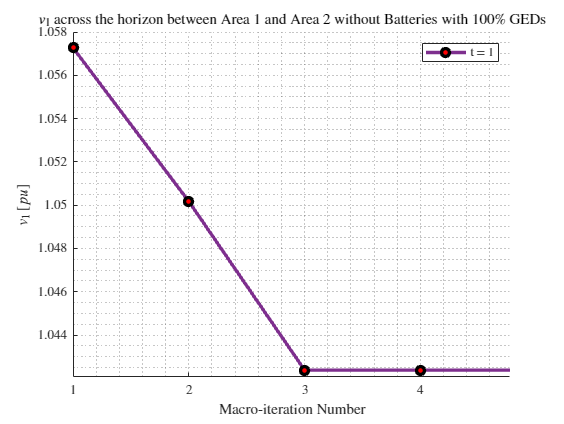

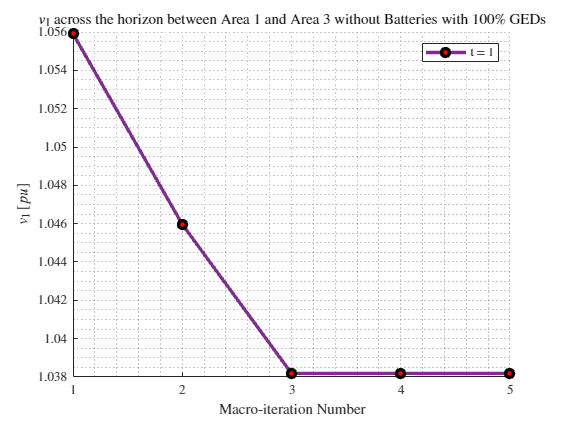

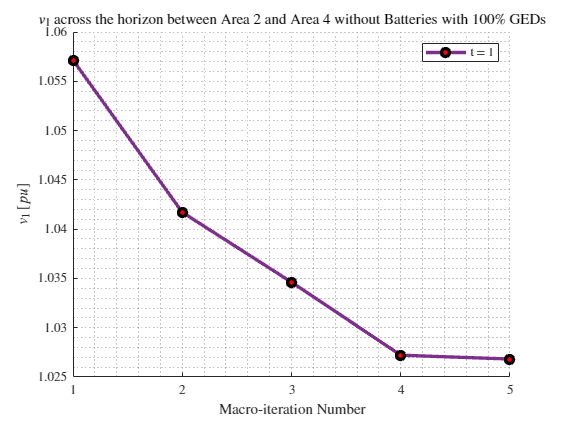

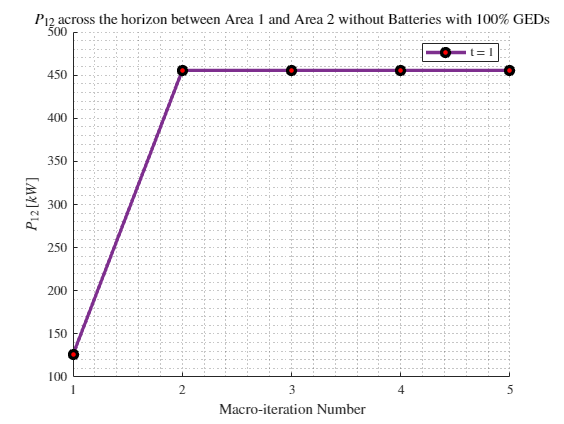

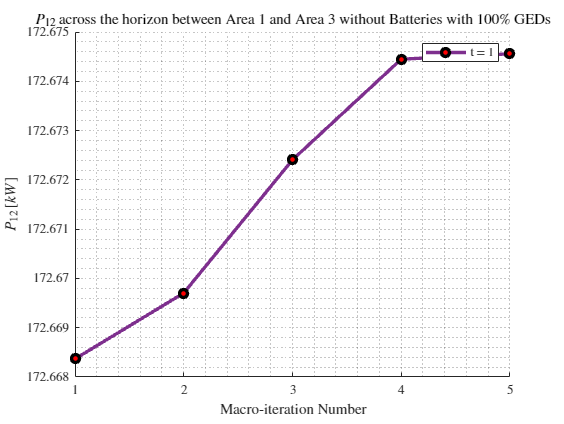

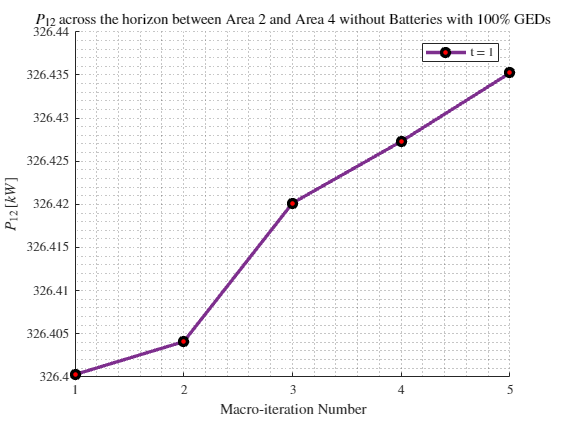

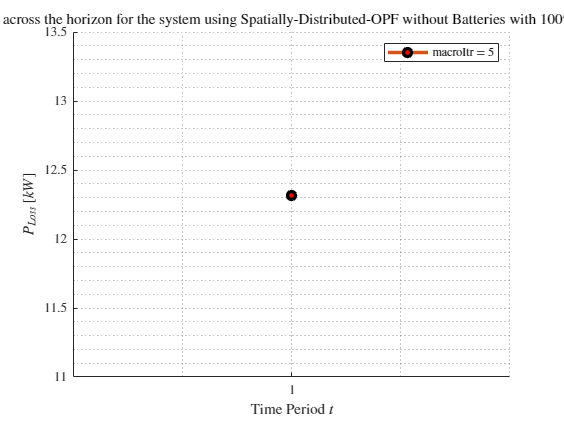

PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
restuls.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results, simInfo, sysInfo)

grandTotalTime = toc(start)

grandTotalTime = 59.4630

    
lineLoss_kW = 0;

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW = lineLoss_kW + lineLoss_Area_kW;

    genCost_Area_dollars = areaInfo.PSubsCost_allT * 1e-2;
    genCost_dollars = genCost_dollars + genCost_Area_dollars;

end
area1Info = sysInfo.Area{1};
genCost_dollars = area1Info.PSubsCost_allT * 1e-2;

substationPower_kW = sum(area1Info.P_Area_1toT(1, :))*kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 1


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['Line Loss: ', num2str(lineLoss_kW),' kW'])                       

Line Loss: 12.3168 kW


disp(['Substation Power: ', num2str(substationPower_kW),' kW'])

Substation Power: 809.0872 kW


disp(['Substation Power Cost: ', num2str(genCost_dollars), ' $'])

Substation Power Cost: 28.3181 $


disp(['Number of Macro-Iterations: ', num2str(macroItr)])

Number of Macro-Iterations: 4


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 59.463 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 51.9877 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 24.1469 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));
% systemSolutionName_x = strcat(prefixName, '_optimalSolutions.csv'); % For CSV file

% Determine the string based on whether batteries are included
if ~noBatteries
    battstring = 'withBatteries';
else
    battstring = 'withoutBatteries';
end

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_1_ETRL204-ARYAN_results_withoutBatteries.txt"

